Полиномиальная регрессия

p = [1 2 1];
x = 0:0.1:10;
sz = length(x);
y = polyval(p,x) + rand(1,sz);
plot(x,y,'o');
p_fit = polyfit(x,y,2)

p_fit =     1.0004    1.9929    1.5126


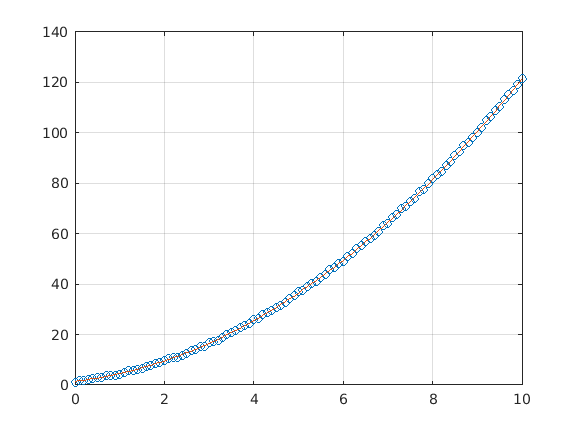

yp = polyval(p_fit,x);
hold on;
grid on;
plot(x,yp);

Несколько графиков в одном

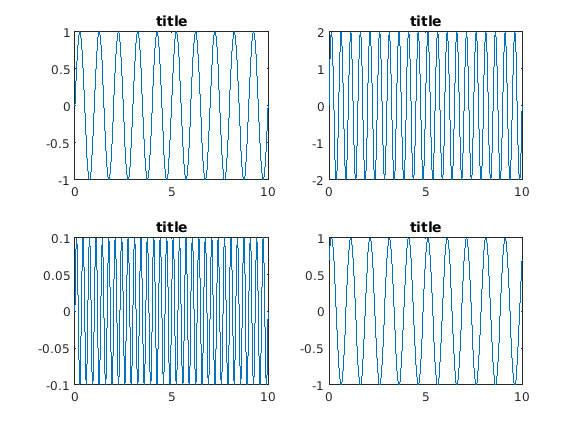

x = 0:0.01:10;
sines = [sin(2*pi*x);2*sin(2*2*pi*x);0.1*sin(3*2*pi*x);sin(2*pi*x+pi/4)];
figure(1);
for i=1:4
    subplot(2,2,i);
    plot(x,sines(i,:));
    title('title');
end

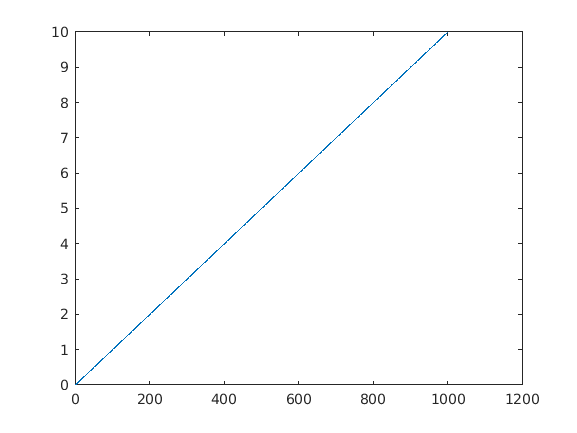

figure(2);
plot(x)

Загрузка текстовых данных

data = load('test.txt');
save('out.csv','data','-ascii');
data_csv = load('out.csv');

Работа со строками

x = "abc"

x = "abc"

y = strcat(x,"def")

y = "abcdef"

x_arr = ['a','b','c']

x_arr = 'abc'

y_arr = ['d','e','f']

y_arr = 'def'

cat = [x_arr, y_arr]

cat = 'abcdef'

x_char = 'abc'

x_char = 'abc'

Операции с матрицами

t = linspace(0,10,100)

t =          0    0.1010    0.2020    0.3030    0.4040    0.5051    0.6061    0.7071    0.8081    0.9091    1.0101    1.1111    1.2121    1.3131    1.4141    1.5152    1.6162    1.7172    1.8182    1.9192    2.0202    2.1212    2.2222    2.3232    2.4242    2.5253    2.6263    2.7273    2.8283    2.9293    3.0303    3.1313    3.2323    3.3333    3.4343    3.5354    3.6364    3.7374    3.8384    3.9394    4.0404    4.1414    4.2424    4.3434    4.4444    4.5455    4.6465    4.7475    4.8485    4.9495


A = diag([1, 2])

A =      1     0
     0     2


B = diag(4:6)

B =      4     0     0
     0     5     0
     0     0     6


Big = blkdiag(A,B)

Big =      1     0     0     0     0
     0     2     0     0     0
     0     0     4     0     0
     0     0     0     5     0
     0     0     0     0     6


AAA = repmat(A,1,3)

AAA =      1     0     1     0     1     0
     0     2     0     2     0     2


d = det(A)

d = 2

lambda = eig(A)

lambda =      1
     2


[v,lambda] = eig(A)

v =      1     0
     0     1


lambda =      1     0
     0     2


left = lambda(1,1)*v(:,1)

left =      1
     0


right = A*v(:,1)

right =      1
     0


left = lambda(2,2)*v(:,2)

left =      0
     2


right = A*v(:,2)

right =      0
     2


A_poly = poly(A)

A_poly =      1    -3     2


Операции с полиномами

A = diag([1, 2])

A =      1     0
     0     2


A_poly = poly(A)

A_poly =      1    -3     2


x = polyval(A_poly,1)

x = 0

r = roots(A_poly)

r =      2
     1


p = poly(r)

p =      1    -3     2


r1 = [j, j];
poly(r1)

ans =    1.0000 + 0.0000i   0.0000 - 2.0000i  -1.0000 + 0.0000i


p2 = [1 2 3 4]

p2 =      1     2     3     4


p_x_p2 = conv(p,p2)

p_x_p2 =      1    -1    -1    -1    -6     8


%deconv
p2_der = polyder(p2)

p2_der =      3     4     3


Лямбда-выражения

f = @(x,y)( x + y);
z = f(1,2)

z = 3

Просто функции

x = test_func(1)

x = 0

%y = test() %не сработает
%y = local_f() %тоже нет